## load dataset

dataset = load("dataset.mat").result_mat;

first_magnitude = dataset(:, 12:112);
second_magnitude = dataset(:, 113:213);
third_magnitude = dataset(:, 214:314);
fourth_magnitude = dataset(:, 315:415);

label = dataset(:, 416);
cate = categorical(label);

% concatenate
zip_data = cat(3, first_magnitude, second_magnitude, third_magnitude, fourth_magnitude)

zip_data = zip_data(:,:,1) =

    0.0044    0.0044    0.0043    0.0041    0.0039    0.0036    0.0033    0.0030    0.0027    0.0024    0.0021    0.0019    0.0018    0.0016    0.0015    0.0015    0.0014    0.0014    0.0014    0.0014    0.0014    0.0014    0.0015    0.0017    0.0020    0.0024    0.0030    0.0036    0.0044    0.0054    0.0063    0.0073    0.0082    0.0090    0.0096    0.0100    0.0101    0.0100    0.0097    0.0092    0.0085    0.0077    0.0068    0.0059    0.0051    0.0043    0.0036    0.0030    0.0025    0.0021    0.0018    0.0015    0.0013    0.0011    0.0010    0.0009    0.0008    0.0007    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0009    0.0009    0.0008    0.0008    0.0007    0.0006    0.0005    0.0005    0.0004    0.0003    0.0003    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001

zip_data = StatisticalNormaliz(zip_data, 'standard');

% split dataset as train and test
[train_idx, ~, test_idx] = dividerand(size(zip_data, 1), 0.8, 0, 0.2);
% slice training data with train indexes 
%(take training indexes in all 10 features)
x_train = zip_data(train_idx, :, :);
y_train = cate(train_idx, :);
% select test data
x_test = zip_data(test_idx, :, :);
y_test = cate(test_idx, :);

x_train = cellfun(@squeeze, num2cell(x_train, [3 2]), 'UniformOutput', false)

x_train = 210×1 cell 数组
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}


x_test = cellfun(@squeeze, num2cell(x_test, [3 2]), 'UniformOutput', false)

x_test = 52×1 cell 数组
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}



whole_data = cellfun(@squeeze, num2cell(zip_data, [3 2]), 'UniformOutput', false)

whole_data = 262×1 cell 数组
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}


whole_label = cate

whole_label = 262×1 categorical 数组
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     1 


## build model

inputSize = 4;
numHiddenUnits1 = 20;
numHiddenUnits2 = 20;
numClasses = 4;

layers = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits1,'OutputMode','sequence')
    dropoutLayer(0.4)
    lstmLayer(numHiddenUnits2,'OutputMode','last')
    dropoutLayer(0.5)
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer]

## set train config

cnnMaxEpochs = 200;
% miniBatchSize = size(x_train, 1);
cnnMiniBatchSize = 30;
cnnLearnRate = 0.001;

options = trainingOptions('adam', ...
    'ExecutionEnvironment','cpu', ...
    'MaxEpochs',cnnMaxEpochs, ...
    'MiniBatchSize',cnnMiniBatchSize, ...
    'Shuffle',"every-epoch", ...
    'InitialLearnRate', cnnLearnRate, ...
    'GradientThreshold',1, ...
    'Verbose',false, ...
    'Plots','training-progress', ...
    'ValidationData',{x_test,y_test});

## TRAIN

net = trainNetwork(x_train, y_train, layers, options);

## TEST

y_pred = classify(net, x_test, 'MiniBatchSize', cnnMiniBatchSize);
acc = sum(y_pred == y_test)./numel(y_test)

y_pred

## observe lstm layer output

% analyzeNetwork(net)
layer = "lstm_2";
featuresTrain = activations(net,whole_data,layer,OutputAs="rows");

Y = tsne(featuresTrain);
gscatter(Y(:,1),Y(:,2),whole_label)

## 1-D CNN

cnnMaxEpochs = 200;
% cnnMiniBatchSize = size(x_train, 1);
cnnMiniBatchSize = 30;
cnnLearnRate = 0.001;

cnnOptions = trainingOptions('adam', ...
    'ExecutionEnvironment','cpu', ...
    'MaxEpochs',cnnMaxEpochs, ...
    'MiniBatchSize',cnnMiniBatchSize, ...
    'Shuffle',"every-epoch", ...
    'InitialLearnRate', cnnLearnRate, ...
    'GradientThreshold',1, ...
    'Verbose',false, ...
    'Plots','training-progress', ...
    'ValidationData',{x_test,y_test});

cnnlayers = [
    sequenceInputLayer(4, 'MinLength', 4)
    convolution1dLayer(4,100)
    reluLayer
    globalMaxPooling1dLayer
    fullyConnectedLayer(4)
    softmaxLayer
    classificationLayer]

cnnnet = trainNetwork(x_train, y_train, cnnlayers, cnnOptions);

cnnlayers

hiddenSizes = 80;                   %隐藏层数
patnet = patternnet(hiddenSizes);       %初始化模式识别神经网络
view(patnet)                            %查看神经网络结构

patnettrain = train(patnet,dataset(train_idx, 1:11).',onehot_train.'); %训练网络

testLen = length(test_idx);                            %测试集长度
val = sim(patnettrain, dataset(test_idx, 1:11).');                %计算测试集分类结果
classes = vec2ind(val);                     %将分类结果转换为class
r = sum(categorical(classes) == y_test.')/(testLen);  %计算正确率
disp(['模式识别的正确率为',num2str(r)])                   %打印结果

% combineeeee = [first_magnitude(:) second_magnitude(:) third_magnitude(:) fourth_magnitude(:)].'

onehot_train = onehotencode(categorical(dataset(train_idx, end)), 2)
onehot_test = onehotencode(categorical(dataset(test_idx, end)), 2)

y_test

## LDA

MdlLinear = fitcdiscr(dataset(train_idx, 1:11), y_train);

MdPred = predict(MdlLinear, dataset(test_idx, 1:11))
sum(categorical(MdPred) == y_test)/(length(y_test));

lstmdata = cellfun(@squeeze, num2cell(zip_data, [3 2]), 'UniformOutput', false)

lstmdata = 262×1 cell 数组
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}
    {4×101 double}


singlemat = squeeze(permute(single(zip_data), [1 3 2]))

singlemat = 262×4×101 single 数组
singlemat(:,:,1) =

    0.6015   -0.3546   -1.1037   -0.8046
   -0.5767   -0.8076   -1.0638   -0.8734
   -0.8156   -1.0333   -0.6991   -0.7484
   -0.6787   -1.0120   -0.6509   -0.6554
    1.0257   -1.0500   -0.5113   -0.4007
    0.8241    2.3553   -0.0178    1.3459
    0.6612    0.9204   -0.8567   -0.8282
    0.4475   -0.8004   -0.9139   -0.8352
   -1.3667   -0.9902   -1.1178   -1.4041
   -0.4024   -0.1580    0.8143    0.5484
   -0.8508   -0.2296   -0.9012   -0.6739
   -1.0059   -0.8878   -1.0453   -1.2927
    0.6346   -0.8185   -0.3565   -0.3738
   -0.4202    1.6352    0.2618   -0.9925
    1.0482   -0.6564   -0.9239   -0.0023
    1.0873    1.9853    2.0864    0.7319
   -0.1706   -0.6447   -1.1890   -0.8619
   -1.2792   -0.9248   -0.9875   -0.4072
   -1.0334   -0.5317   -0.0504    1.3233
   -1.1373   -0.8960   -1.0862   -1.2228
    2.0026   -0.0886   -0.5263   -0.5095
    1.3369   -0.6650   -0.9616   -1.2112
   -0.6243   -0.7485   -0.4180   -0.6638
   -0

lstmdataStore = arrayDatastore(lstmdata)

lstmdataStore =   ArrayDatastore - 属性:

              ReadSize: 1
    IterationDimension: 1
            OutputType: "cell"


testX = arrayDatastore(combineeeee.', 'ReadSize', 4, 'IterationDimension', 2)

函数或变量 'combineeeee' 无法识别。

testY = arrayDatastore(categorical(label))
datasettttt = combine(testX, testY)

read(testX)

readall(test)

inputSize = 4;
numHiddenUnits = 100;
numClasses = 4;

layers = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits,'OutputMode','last')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer]

layers =   具有以下层的 5×1 Layer 数组:

     1   ''   序列输入    序列输入: 4 个维度
     2   ''   LSTM      LSTM: 100 个隐藏单元
     3   ''   全连接     4 全连接层
     4   ''   Softmax   softmax
     5   ''   分类输出    crossentropyex

maxEpochs = 70;
miniBatchSize = 20;
learnRate = 0.001;

options = trainingOptions('adam', ...
    'ExecutionEnvironment','cpu', ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'InitialLearnRate', learnRate, ...
    'GradientThreshold',1, ...
    'Verbose',false, ...
    'Plots','training-progress');

net = trainNetwork(lstmdata, cate, layers, options);

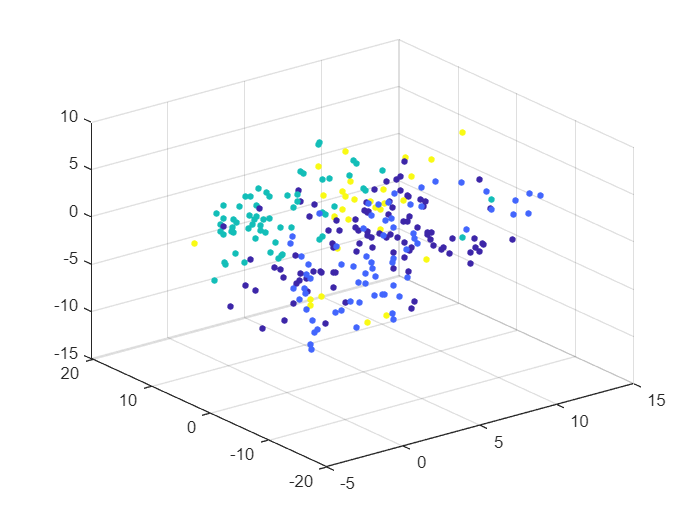

Y2 = tsne([dataset(:, 1:2) dataset(:, 4:end-1)], 'Algorithm','barneshut','NumPCAComponents',50,'NumDimensions',3,'Distance',"cityblock",'Standardize',true);
scatter3(Y2(:,1),Y2(:,2),Y2(:,3),15,dataset(:, end),'filled')

algo = 'exact';
perplexity = 30;

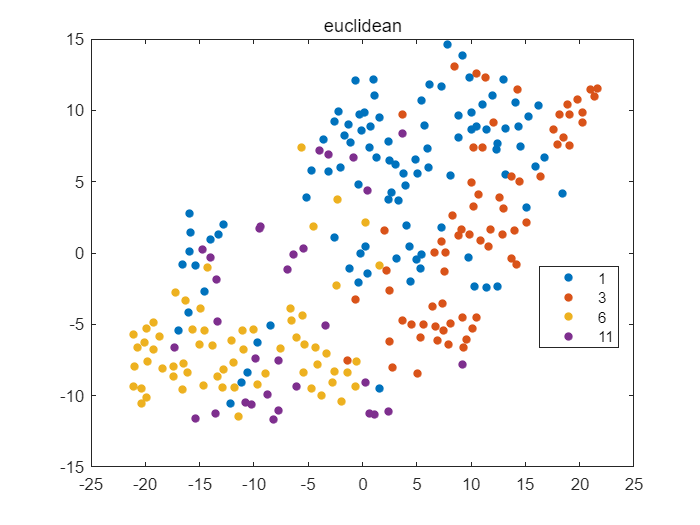

rng('default') % for reproducibility
meas = [dataset(:, 1:2) dataset(:, 4:end-1)];
species = dataset(:, end);
Y = tsne(meas,'Algorithm',algo,'Distance','euclidean', 'Perplexity', perplexity);
% subplot(2, 2, 1)
gscatter(Y(:,1),Y(:,2),species)
title('euclidean')

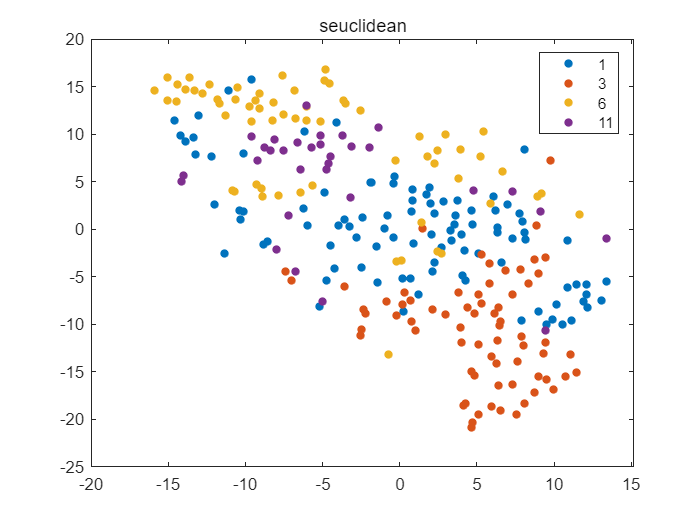


rng('default') % for fair comparison
Y = tsne(meas,'Algorithm',algo,'Distance','seuclidean', 'Perplexity', perplexity);
% subplot(2, 2, 2)
gscatter(Y(:,1),Y(:,2),species)
title('seuclidean')

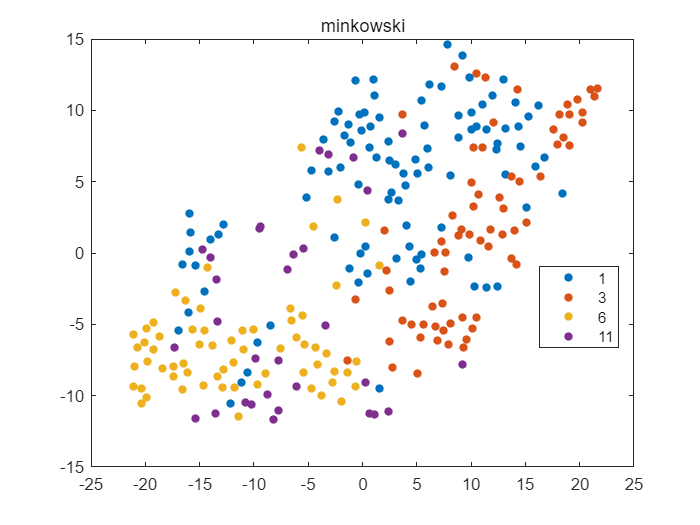


rng('default') % for fair comparison
Y = tsne(meas,'Algorithm',algo,'Distance','minkowski', 'Perplexity', perplexity);
% subplot(2, 2, 1)
gscatter(Y(:,1),Y(:,2),species)
title('minkowski')

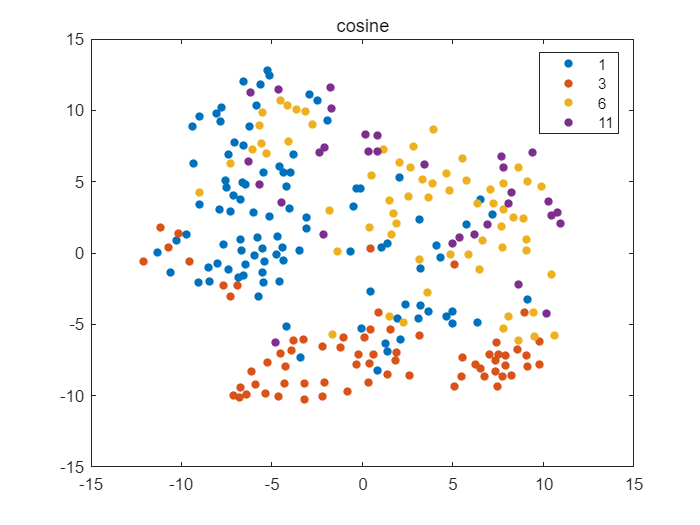


rng('default') % for fair comparison
Y = tsne(meas,'Algorithm',algo,'Distance','cosine', 'Perplexity', perplexity);
% subplot(2, 2, 2)
gscatter(Y(:,1),Y(:,2),species)
title('cosine')

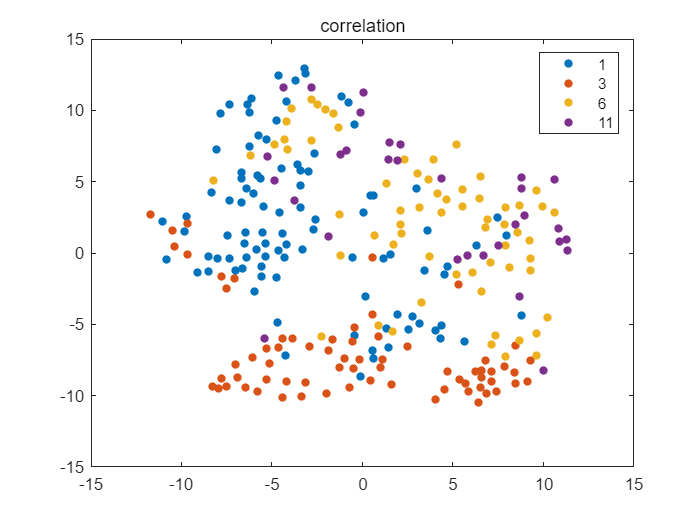


rng('default') % for fair comparison
Y = tsne(meas,'Algorithm',algo,'Distance','correlation', 'Perplexity', perplexity);
% subplot(2, 2, 1)
gscatter(Y(:,1),Y(:,2),species)
title('correlation')

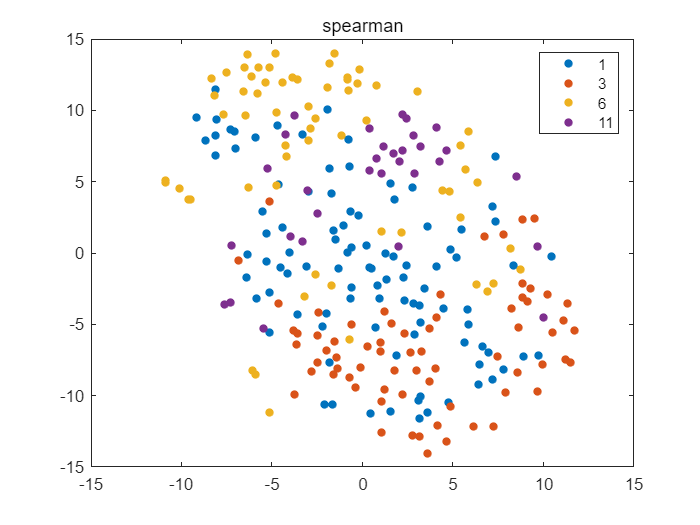


rng('default') % for fair comparison
Y = tsne(meas,'Algorithm',algo,'Distance','spearman', 'Perplexity', perplexity);
% subplot(2, 2, 2)
gscatter(Y(:,1),Y(:,2),species)
title('spearman')

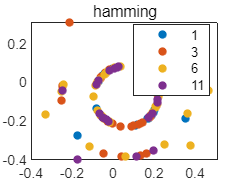


rng('default') % for fair comparison
Y = tsne(meas,'Algorithm',algo,'Distance','hamming', 'Perplexity', perplexity);
% subplot(2, 2, 1)
gscatter(Y(:,1),Y(:,2),species)
title('hamming')

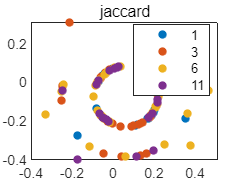


rng('default') % for fair comparison
Y = tsne(meas,'Algorithm',algo,'Distance','jaccard', 'Perplexity', perplexity);
% subplot(2, 2, 2)
gscatter(Y(:,1),Y(:,2),species)
title('jaccard')